# Modelado, análisis, simulación y control de un fenómeno vibratorio

Adrián Augusto Ferrer Orgaz A01749394

Carlos de Jesús Ávila González A01750220

Elisa María Bonilla Martín A01028576

Enrique Maldonado Chavarría A01652370

Control de un Edificio de 3 masas sujeto a control en lazo cerrado:

## Parámetros iniciales:

Masas, coeficientes de amortiguamiento y constantes de rigidez de la estructura:

clear
m = [6 5 4];
b = [0.08 0.05 0.04];
k = [5000 4800 5100];

Matrices Q y R para optimización con control óptimo:

Q_1 = eye(3*2);
R_1 = eye(3);

Q = eye(4*2);
R = eye(4);

Perturbación sísmica y periodo a simular:

r = @(a,w,t) a.*sin(w.*t);
alpha = 1;
omega = 14.6176;
t_int = 0:0.01:1000;
simTitle = ["Simulación del Desplazamiento Lateral" "\omega = "+omega+", \alpha = "+alpha]

simTitle = 1×2 string array
    "Simulación del Desplazamiento Lateral"    "\omega = 14.6176, \alpha = 1"


## Caso 0: Sin Control

### Sistema en Espacio de Estados

Estabilidad Del Sistema


ans =   -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


DISEÑO DE CONTROL
Observabilidad
Numero de estados:


ans = 6

Rango de la matriz de observabilidad


ans = 6

Controlabilidad
Rango de la matriz de controlabilidad


ans = 0

ESTABILIDAD DEL SISTEMA


ans =   -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


DIAGRAMAS DE BODE DE MAGNUTUD Y FASE


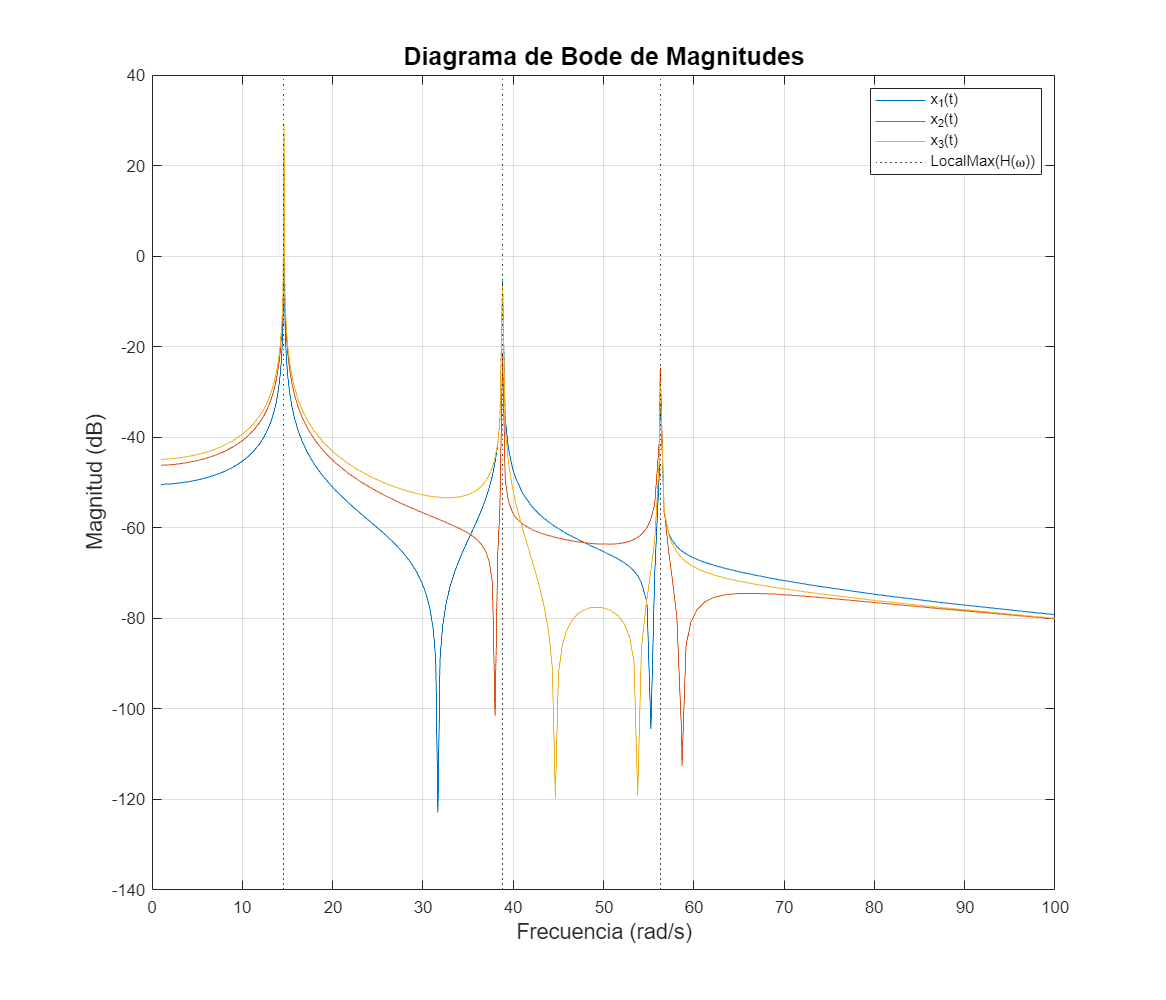

Frecuencias de escalamiento máximo (rad/s):
   14.6176   38.8200   56.2820

Escalamientos máximos (dB):
Para x_1(t):
22.865109 -5.312330 -30.297584 
Para x_2(t):
27.846999 -21.342915 -24.641466 
Para x_3(t):
29.440218 -6.542505 -28.072891 


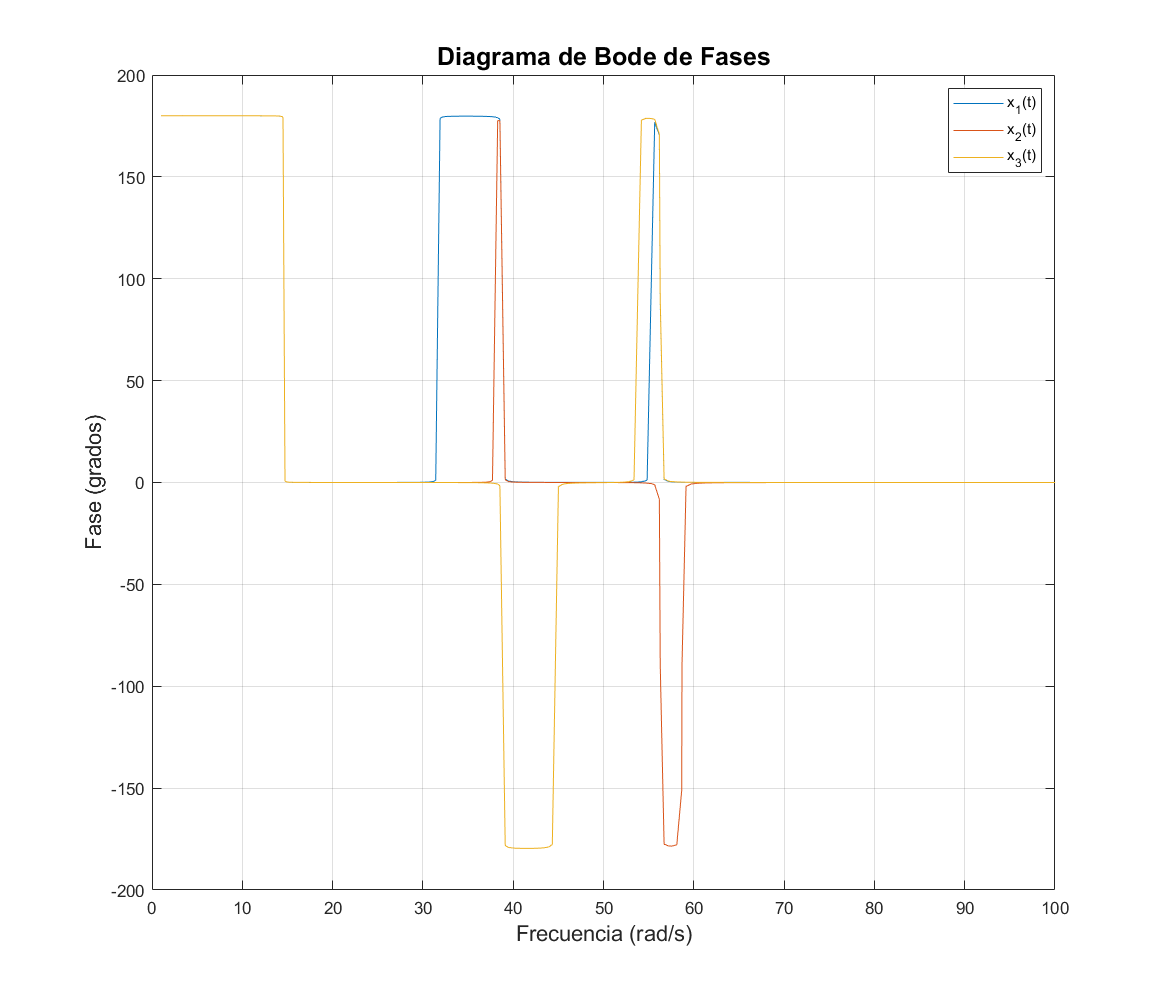

SIMULACIÓN


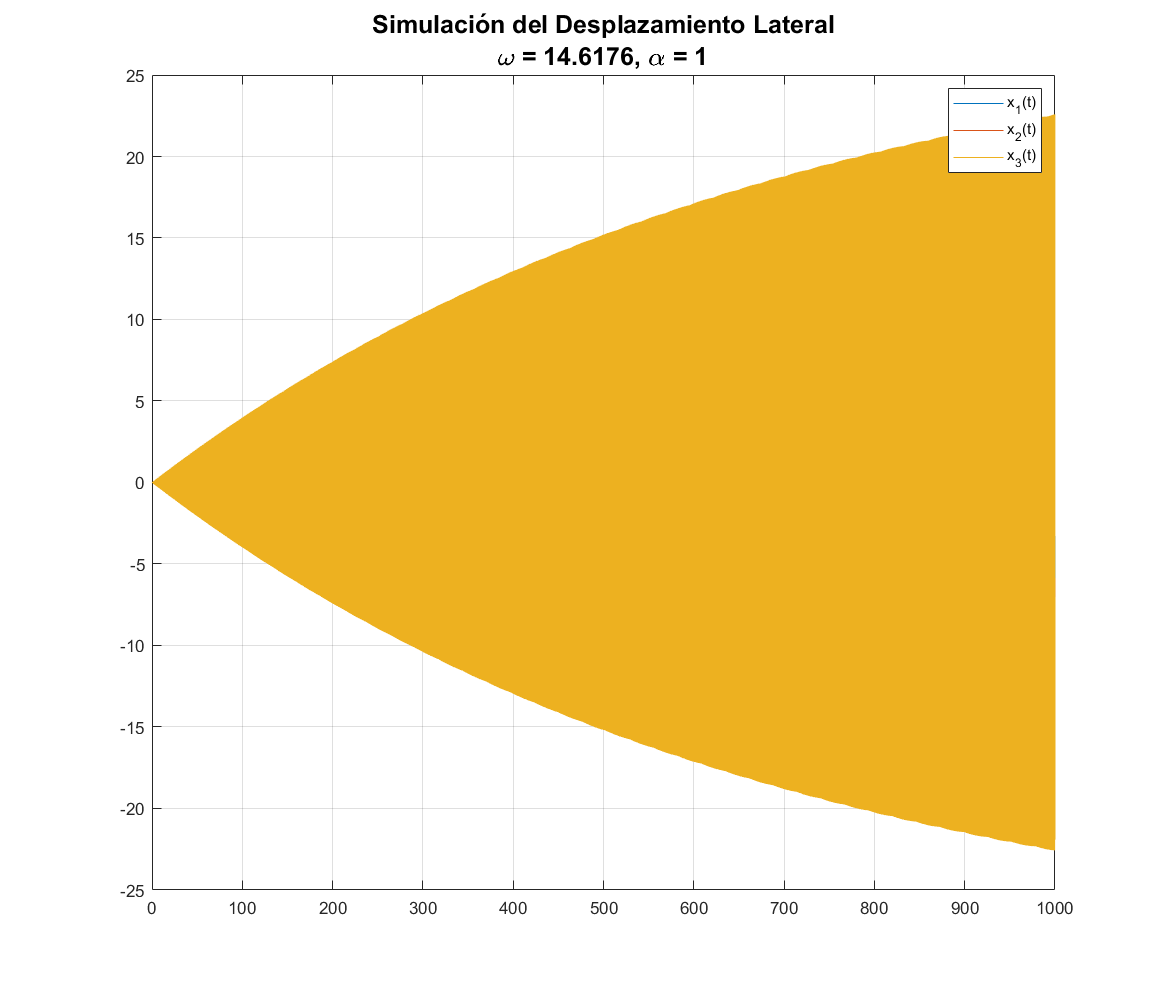

%Vector de masa, coeficiente de amortiguamiento y constante de rigidez de
%la masa de amortiguación activa vector con 0 ya que no se utiliza
%El vector utilizado en las siguientes simulaciones: [0.5 0.06 4500]
mbkd= [0];

z_0 = zeros(2*3,1); %Condiciones iniciales

r_theta = [0 0 0]; %Vector de posición de los actuadores hidráulicos en los pisos

[G,L,~] = sim_Control(m,b,k,Q_1,R_1,r(alpha, omega, t_int),t_int,mbkd,r_theta, simTitle);

## Caso 1: Actuadores Hidráulicos

### Sistema en Espacio de Estados

Estabilidad Del Sistema


ans =   -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


DISEÑO DE CONTROL
Observabilidad
Numero de estados:


ans = 6

Rango de la matriz de observabilidad


ans = 6

Controlabilidad
Rango de la matriz de controlabilidad


ans = 6

ESTABILIDAD DEL SISTEMA


ans =   -0.1811 +56.2818i
  -0.1811 -56.2818i
  -0.1216 +38.8198i
  -0.1216 -38.8198i
  -0.0487 +14.6175i
  -0.0487 -14.6175i


DIAGRAMAS DE BODE DE MAGNUTUD Y FASE


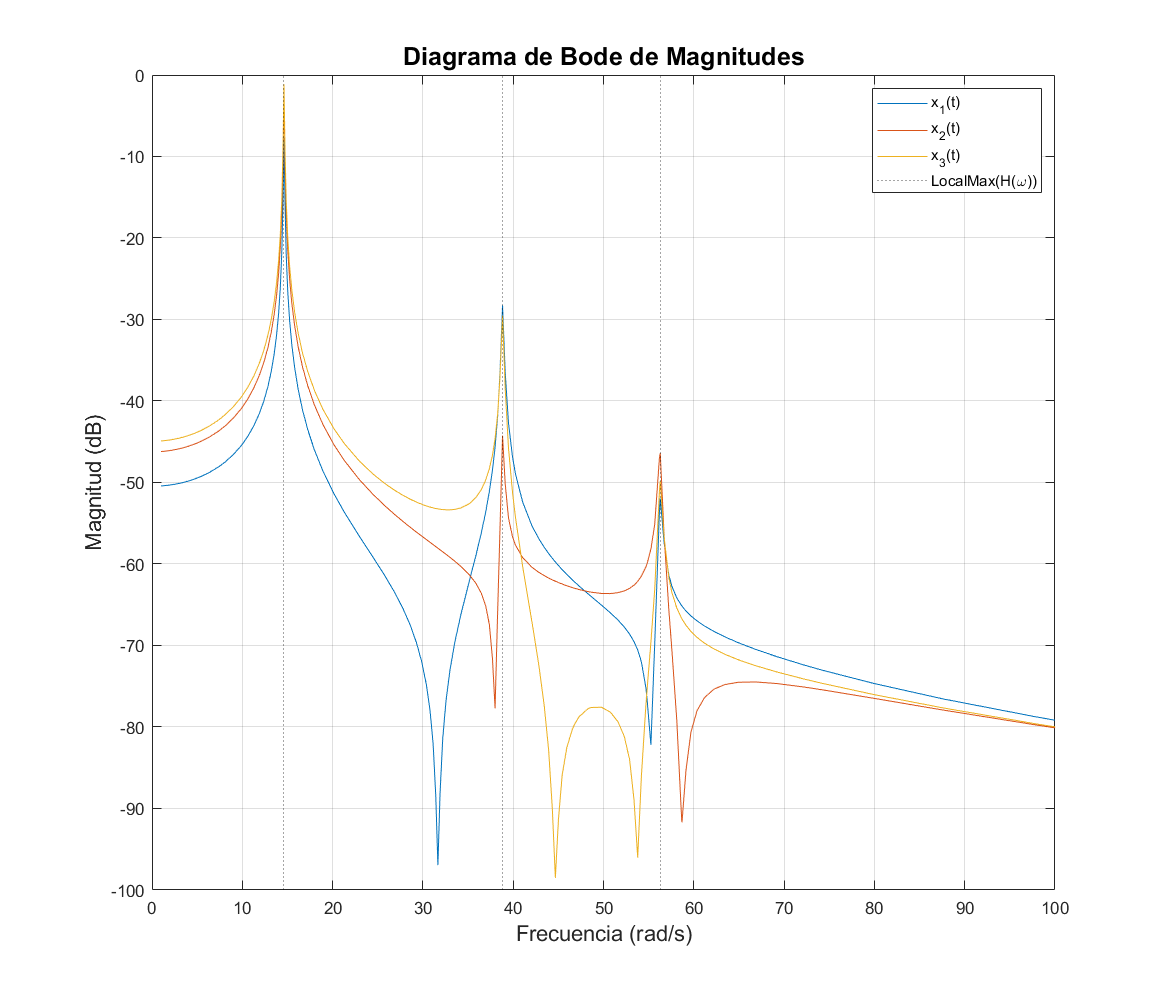

Frecuencias de escalamiento máximo (rad/s):
   14.6174   38.8196   56.2815

Escalamientos máximos (dB):
Para x_1(t):
-7.703652 -28.299433 -51.947933 
Para x_2(t):
-2.721820 -44.248334 -46.384939 
Para x_3(t):
-1.128630 -29.527114 -49.826061 


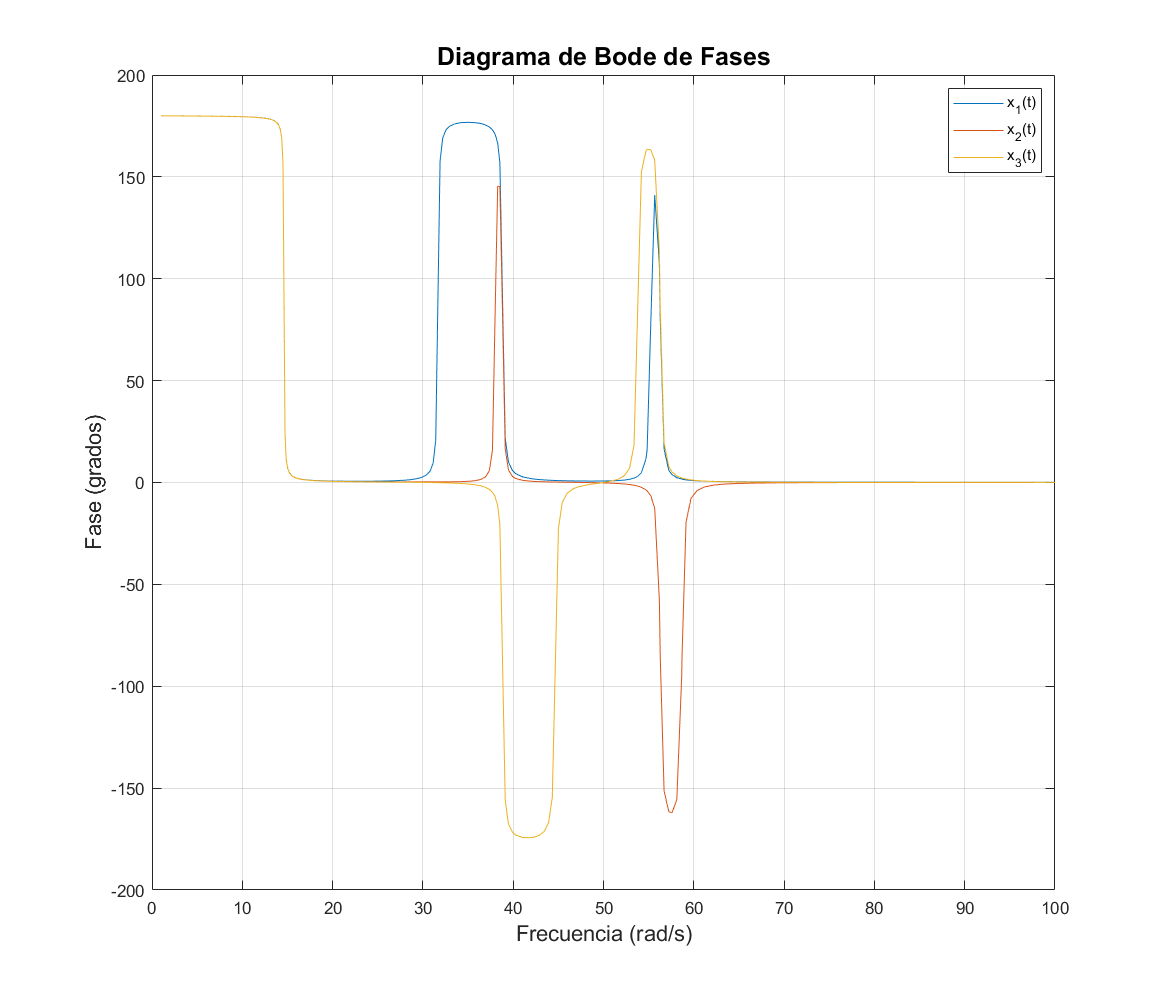

SIMULACIÓN


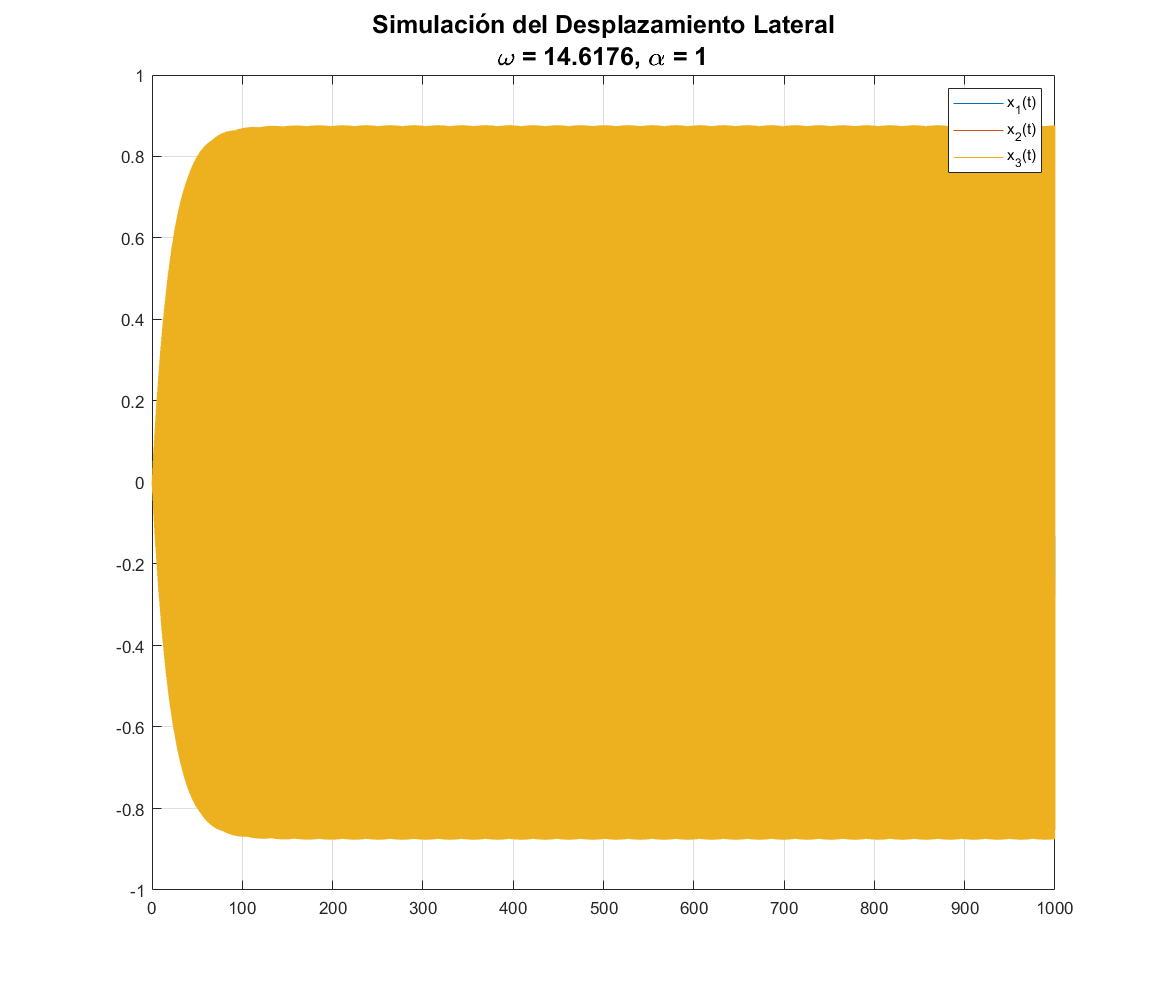

mbkd_1 = [0];

z_0_1 = zeros(2*3,1);

r_theta_1 = [1 1 1]; 

[G1,L1,~] = sim_Control(m,b,k,Q_1,R_1,r(alpha, omega, t_int),t_int,mbkd_1,r_theta_1, simTitle);

## Caso 2: AMD

### Sistema en Espacio de Estados

Estabilidad Del Sistema


ans =   -0.0600 +94.8683i
  -0.0600 -94.8683i
  -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


DISEÑO DE CONTROL
Observabilidad
Numero de estados:


ans = 8

Rango de la matriz de observabilidad


ans = 8

Controlabilidad
Rango de la matriz de controlabilidad


ans = 8

ESTABILIDAD DEL SISTEMA


ans =   -1.1508 +94.8658i
  -1.1508 -94.8658i
  -0.0684 +56.2808i
  -0.0684 -56.2808i
  -0.0809 +38.8192i
  -0.0809 -38.8192i
  -0.0982 +14.6171i
  -0.0982 -14.6171i


DIAGRAMAS DE BODE DE MAGNUTUD Y FASE


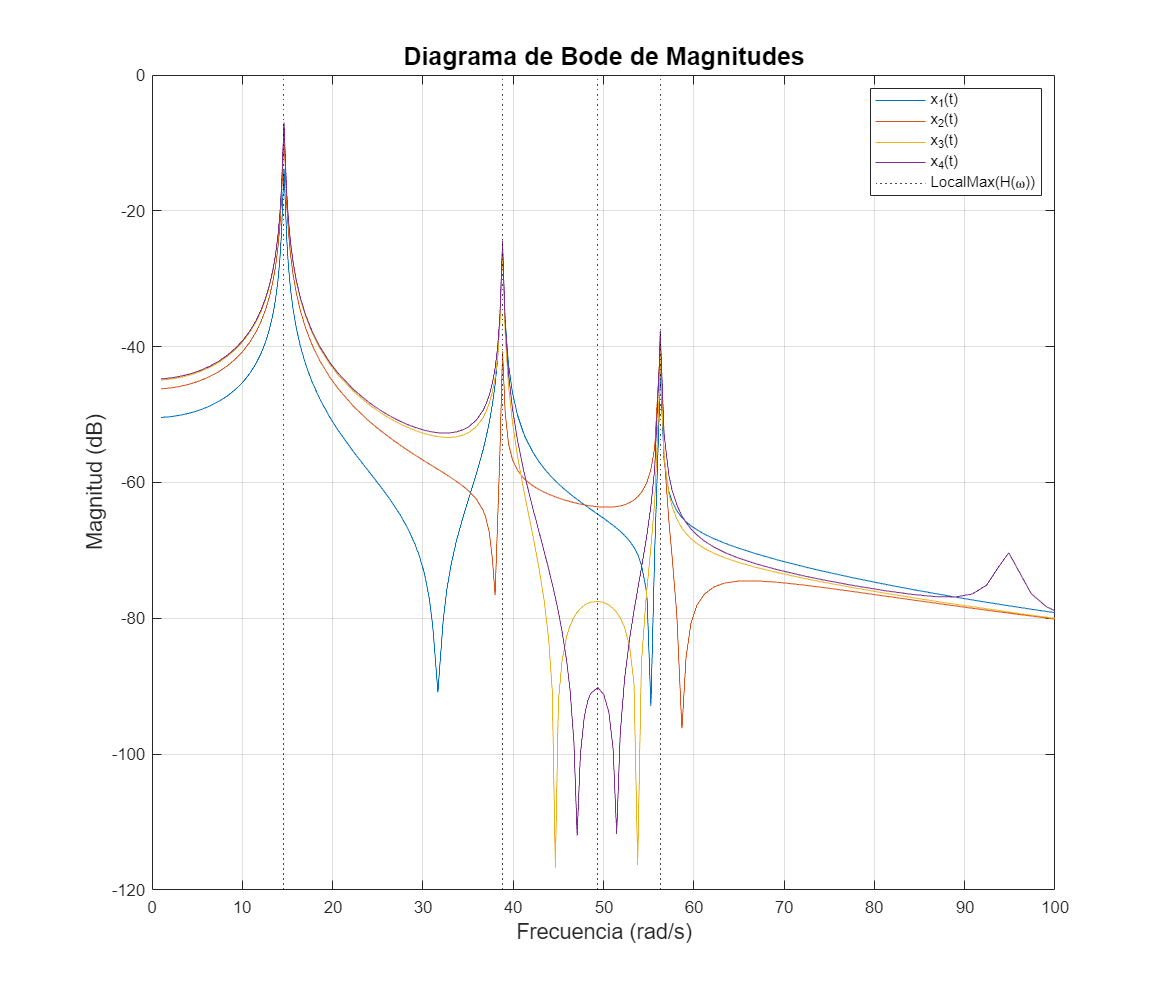

Frecuencias de escalamiento máximo (rad/s):
   14.6168   38.8191   49.3696   56.2808

Escalamientos máximos (dB):
Para x_1(t):
-13.799446 -24.753969 -64.669300 -43.594356 
Para x_2(t):
-8.817726 -40.681876 -63.571074 -37.938886 
Para x_3(t):
-7.224506 -25.986542 -77.500024 -41.382327 
Para x_4(t):
-7.015813 -24.394939 -90.193639 -37.611539 


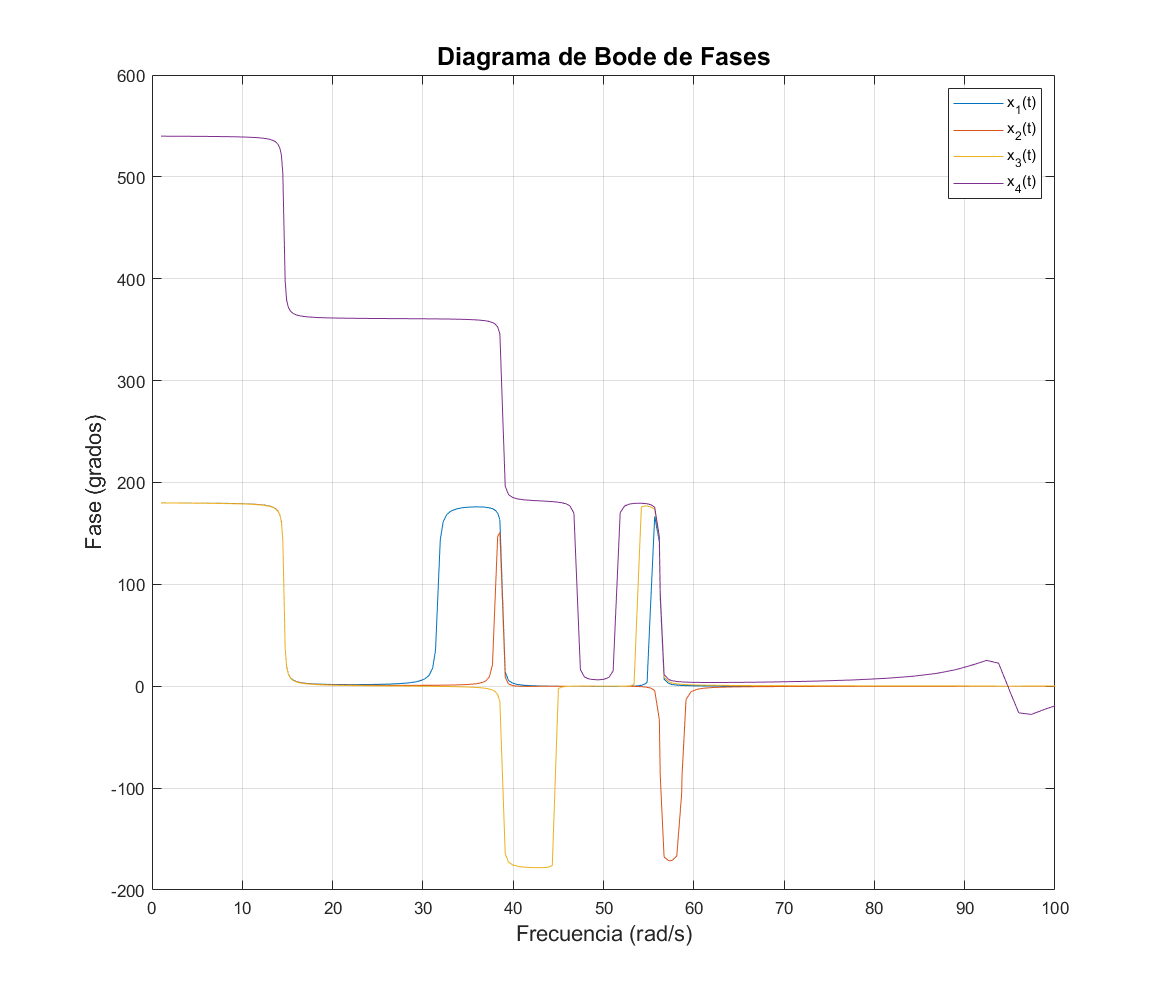

SIMULACIÓN


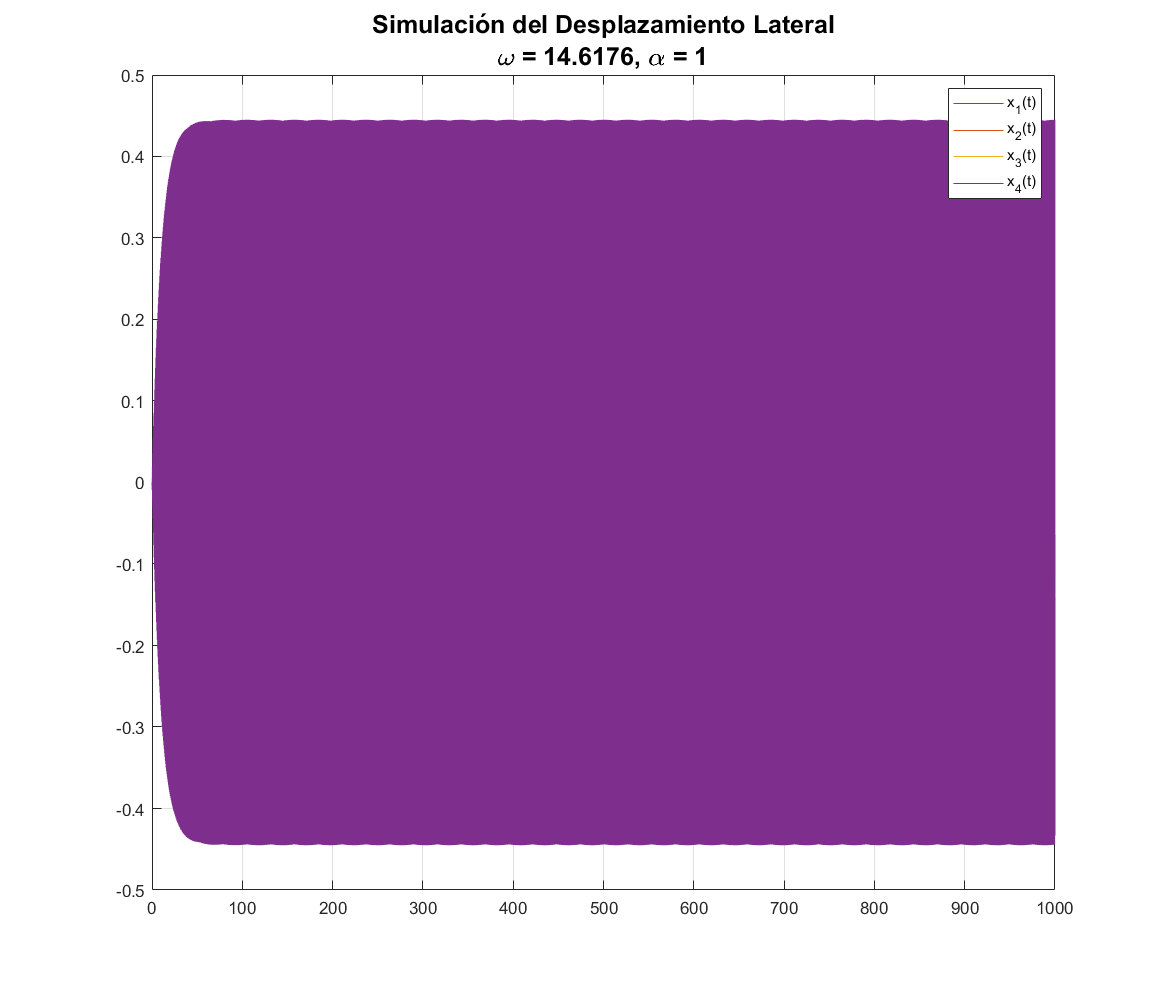

mbkd_2 = [0.5 0.06 4500];

z_0_2 = zeros(2*4,1);

r_theta_2 = [0 0 0];

[G2,L2,~] = sim_Control(m,b,k,Q,R,r(alpha, omega, t_int),t_int,mbkd_2,r_theta_2, simTitle);

## Caso 3: Actuadores Hidráulicos y AMD

### Sistema en Espacio de Estados

Estabilidad Del Sistema


ans =   -0.0600 +94.8683i
  -0.0600 -94.8683i
  -0.0148 +56.2820i
  -0.0148 -56.2820i
  -0.0086 +38.8200i
  -0.0086 -38.8200i
  -0.0014 +14.6176i
  -0.0014 -14.6176i


DISEÑO DE CONTROL
Observabilidad
Numero de estados:


ans = 8

Rango de la matriz de observabilidad


ans = 8

Controlabilidad
Rango de la matriz de controlabilidad


ans = 8

ESTABILIDAD DEL SISTEMA


ans =   -1.1637 +94.8665i
  -1.1637 -94.8665i
  -0.2401 +56.2800i
  -0.2401 -56.2800i
  -0.1739 +38.8188i
  -0.1739 -38.8188i
  -0.1154 +14.6170i
  -0.1154 -14.6170i


DIAGRAMAS DE BODE DE MAGNUTUD Y FASE


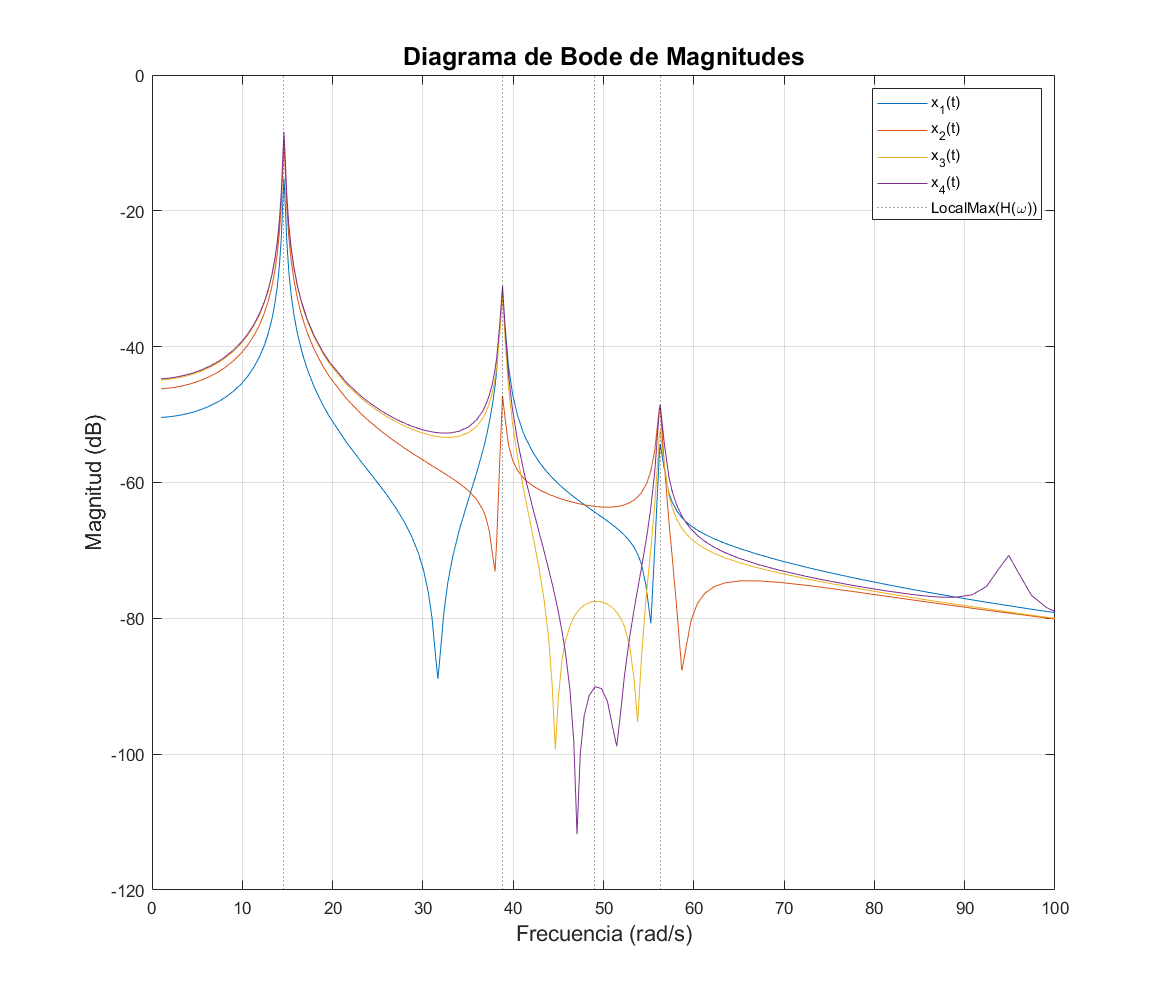

Frecuencias de escalamiento máximo (rad/s):
   14.6165   38.8184   49.0584   56.2795

Escalamientos máximos (dB):
Para x_1(t):
-15.198370 -31.403001 -64.380945 -54.339349 
Para x_2(t):
-10.216770 -47.194320 -63.529050 -48.784600 
Para x_3(t):
-8.623644 -32.635063 -77.497650 -52.268123 
Para x_4(t):
-8.414974 -31.047745 -90.070108 -48.505760 


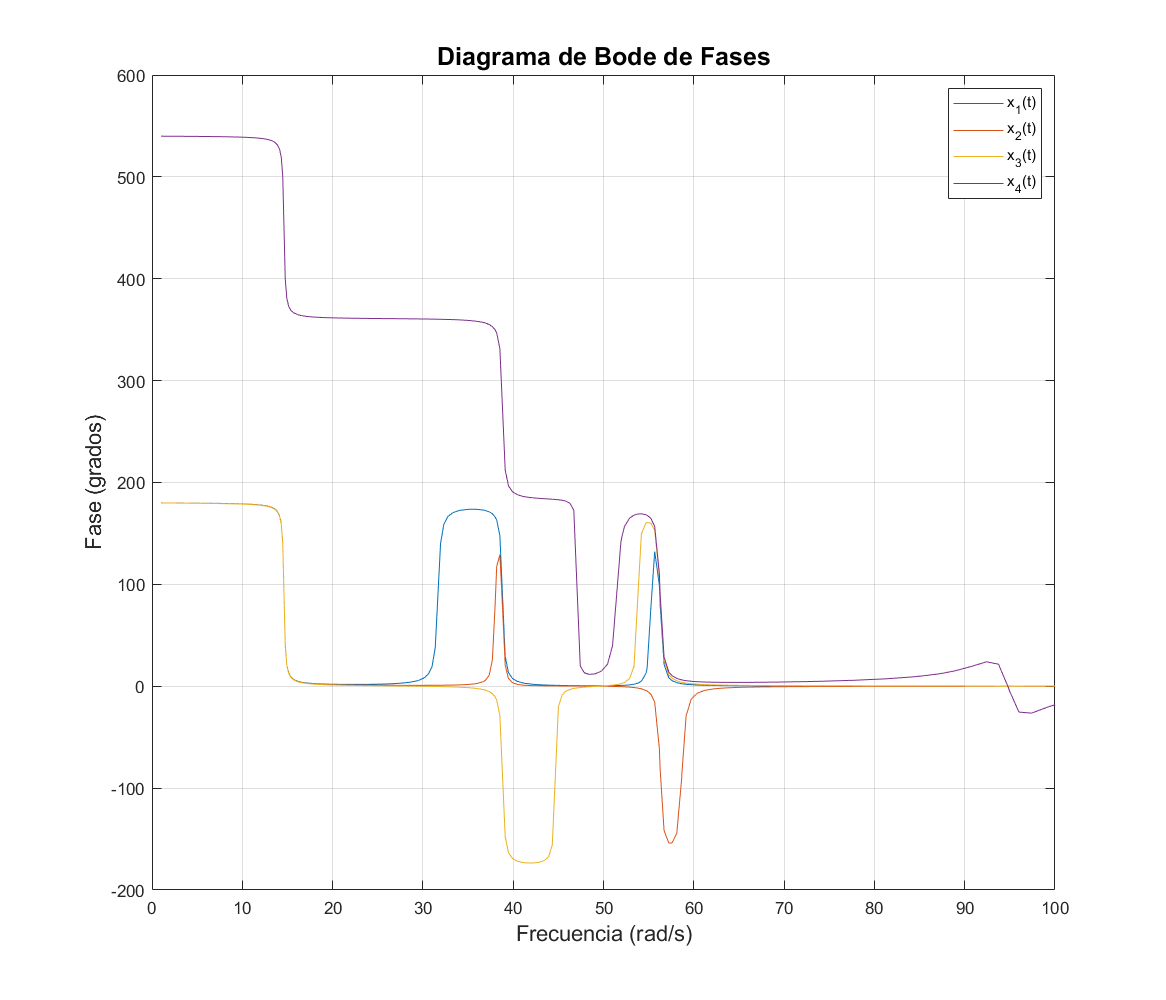

SIMULACIÓN


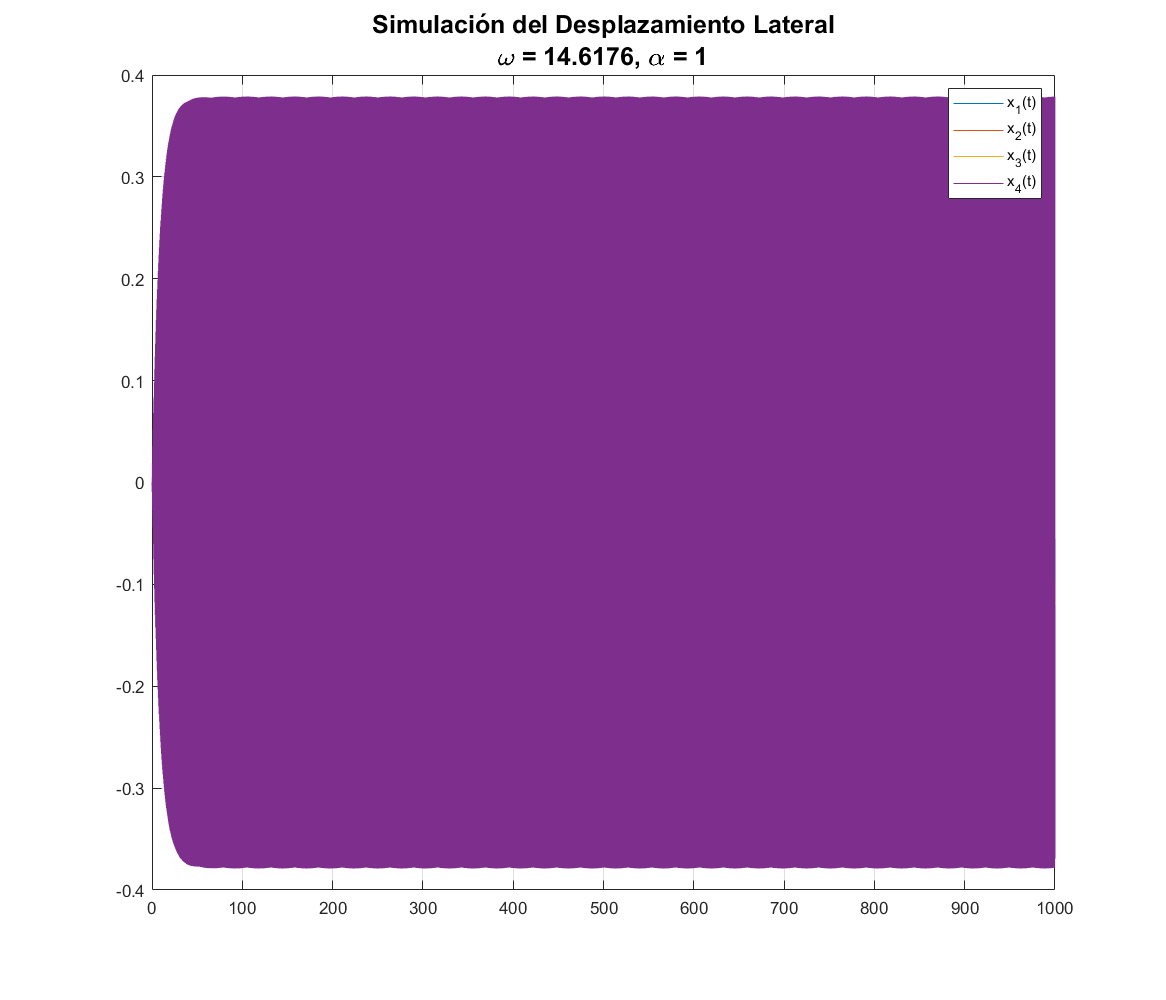

mbkd_3 = [0.5 0.06 4500];

z_0_3 = zeros(2*4,1);

r_theta_3 = [1 1 1];

[G3,L3,~] = sim_Control(m,b,k,Q,R,r(alpha, omega, t_int),t_int,mbkd_3,r_theta_3, simTitle);

## Funciones Auxiliares

function [G,L,sys] = sim_Control(m,b,k,Q,R,r,t_int,mbkd,r_theta, simTitle)

g_bar = gamma_bar(length(m));
theta = MM(r_theta);

if mbkd(1) == 0 % en el caso de control sin masa de amortiguamiento activo
    gamma = g_bar*theta;
    B = BK(b);
    delta = -1*m';
    K = BK(k);
    M = MM(m);
else % en el caso de control con masa de amortiguamiento activo
    gamma = gamma_AMD(g_bar*theta);
    B = BK_AMD(BK(b),mbkd(2));
    delta = -1*[m mbkd(1)]';
    K = BK_AMD(BK(k),mbkd(3));
    M = MM_AMD(MM(m),mbkd(1));
end

n = length(M);

labels = cell(1,n);
for i = 1:n
    labels{1,i} = sprintf("x_%d(t)", i);
end


A = [zeros(n) eye(n); -inv(M)*K -inv(M)*B];
Bu = [zeros(n); M\gamma];
Br =  [zeros(n);MM(M\delta)];
C = [eye(n) zeros(n)];
D = zeros(n);

disp("Estabilidad Del Sistema")
eig(A)
disp("DISEÑO DE CONTROL")
disp("Observabilidad")
disp("Numero de estados:")
n*2
disp("Rango de la matriz de observabilidad")
rank(obsv(A,C))
L = lqr(A', C', Q, R)';
disp("Controlabilidad")
disp("Rango de la matriz de controlabilidad")
rank(ctrb(A, Bu))
G = lqr(A, Bu, Q, R);
disp("ESTABILIDAD DEL SISTEMA")
A_c = A-Bu*G;
eig(A_c)
disp("DIAGRAMAS DE BODE DE MAGNUTUD Y FASE")
sys = ss(A_c, [zeros(n,1);inv(M)*delta], C, zeros(n,1));
BodeAnalysis(sys, n)
disp("SIMULACIÓN")
figure('Position', [100, 100, 1400, 1200])
[y, tOut, ~] = lsim(sys, r, t_int);
plot(tOut, y)
grid on
title(simTitle, "FontSize",15)
legend(labels, "Location", "northeast")

end


function matrix = BK(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    for j = 1:n
        if j == i+1
            matrix(i,j) = -el(i+1);
        elseif j == i-1
            matrix(i,j) = -el(i);
        elseif i==j
            if  i == n && j == n
                matrix(i,j) = el(n);
            else
                matrix(i,j) = el(i)+el(i+1);
            end
        else
            matrix(i,j) = 0;
        end
    end
end
end

function matrix = MM(el)

n = length(el);
matrix = zeros(n);

for i = 1:n
    matrix(i,i) = el(i);

end
end

function matrix = BK_AMD(mat, el)
n = size(mat, 1);
matrix = [mat zeros(n,1); zeros(1,n-1) -el el];
end

function matrix = gamma_bar(n)

matrix = zeros(n);

for i = 1:n
   if i ~= n
        matrix(i, i) = -1;
        matrix(i, i+1) = 1; 
   else 
       matrix(i,i) = -1;
   end
end
end

function matrix = gamma_AMD(mat)
n = size(mat, 1);
matrix = [mat [zeros(n-1,1);-1];zeros(1,n) 1];

end

function matrix = MM_AMD(mat, el)

n = size(mat, 1);

matrix = [mat zeros(n, 1);zeros(1,n) el];

end


function BodeAnalysis(sys, n)
[mag, phase, wout] = bode(sys);
mag = 20*log10(squeeze(mag));
phase = squeeze(phase);

labels = cell(1,n);
for i = 1:n
    labels{1,i} = sprintf("x_%d(t)", i);
end

figure('Position', [100, 100, 1400, 1200])
plot(wout, mag)
hold on
idx = cell(1,n);
freq_res = [];

for i = 1:n
    [~, loc] = findpeaks(mag(i,:));
    idx{1, i} = loc;
    if i ~= 1
        freq_res = intersect(idx{1,i},idx{1,i-1});
    end
end

pks_sis = zeros(n,length(freq_res));


for i=1:length(freq_res)
    pks_sis(:,i) = mag(:,freq_res(i));
    freq_res(i) = wout(freq_res(i));
end


if ~isempty(freq_res)
    xline(freq_res, ":k")
    labels{1, n+1} = "LocalMax(H(\omega))";
end

hold off
title("Diagrama de Bode de Magnitudes", "FontSize",15)
xlim([0 100])
grid on
xlabel("Frecuencia (rad/s)", "FontSize",13)
ylabel("Magnitud (dB)", "FontSize",13)
legend(labels, "Location", "northeast")
if ~isempty(freq_res)
disp("Frecuencias de escalamiento máximo (rad/s):")
disp(freq_res)
disp("Escalamientos máximos (dB):")
for i=1:n
    fprintf("Para x_%d(t):\n", i)
    for j = 1:length(pks_sis(i,:))
        fprintf("%f ",double(pks_sis(i,j)))
    end
    fprintf("\n")
end
end

figure('Position', [100, 100, 1400, 1200])
plot(wout, phase)
title("Diagrama de Bode de Fases", "FontSize",15)
xlim([0 100])
xlabel("Frecuencia (rad/s)", "FontSize",13)
ylabel("Fase (grados)", "FontSize",13)
grid on
legend(labels{1,1:n},"Location", "northeast")
end
